## EEN - 521 Digital Signal and Image Processing

1) Generate the following sequences in MATLAB:

    a) An impulse at t = 0 

clc;
n=-5:5;
n0=input('Enter the Location of impulse = ')

n0 = 0

del= [n-n0==0];
display(del,'Sequence');

Sequence = 1×11 logical array
   0   0   0   0   0   1   0   0   0   0   0


display(n, 'Idices')

Idices =     -5    -4    -3    -2    -1     0     1     2     3     4     5


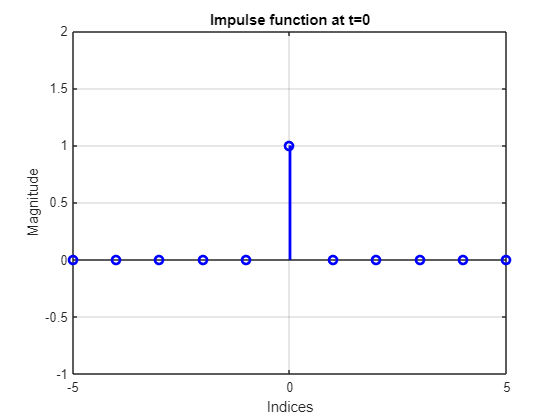

figure;
stem(n,del,'linewidth',2,'color','b'); grid
title("Impulse function at t=0")
xlabel("Indices")
ylabel("Magnitude")
xlim([-5 5])
ylim([-1 2])

    b) Unit step sequence of length N

N=input('Enter the Length of Unit Step Sequence = ')

N = 10

n1=-N/2:N/2-1

n1 =     -5    -4    -3    -2    -1     0     1     2     3     4


u= [(n1-0) >= 0];
display(u,'Sequence');

Sequence = 1×10 logical array
   0   0   0   0   0   1   1   1   1   1


display(n1, 'Idices')

Idices =     -5    -4    -3    -2    -1     0     1     2     3     4


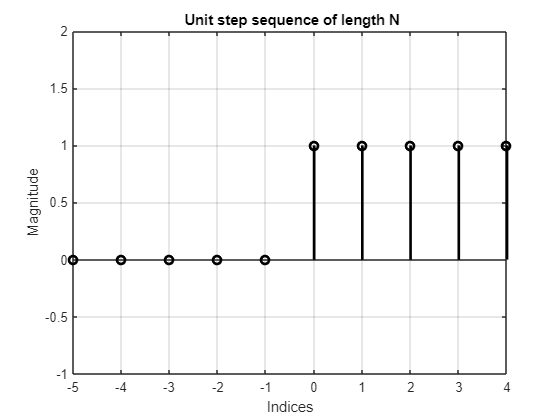

figure;
stem(n1,u,'linewidth',2,'color','k'); grid
title(" Unit step sequence of length N")
xlabel("Indices")
ylabel("Magnitude")
ylim([-1 2])

    c) Ramp signal of length N and slope S

s=input('Enter the Slop of Ramp, s = ');
ramp = s*n1.*u;
display(ramp,'Sequence');

Sequence =      0     0     0     0     0     0     2     4     6     8


display(n1, 'Idices')

Idices =     -5    -4    -3    -2    -1     0     1     2     3     4


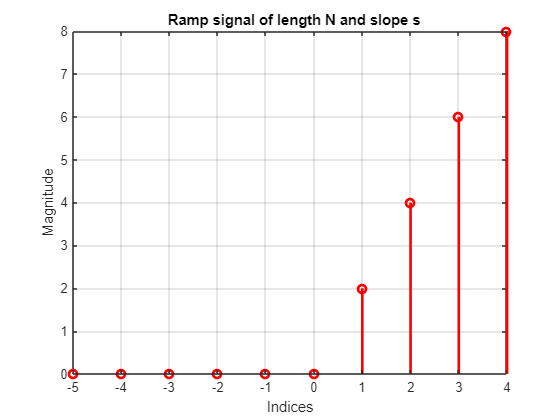

figure
stem(n1,ramp,'linewidth',2,'color','r'); grid
title("  Ramp signal of length N and slope s")
xlabel("Indices")
ylabel("Magnitude")

d) x(n) = 2δ(n + 2) − δ(n − 4), −5 ≤ n ≤ 5  

n = -5:5;
xn = 2*((n+2)==0)-((n-4)==0); % The delta function
display(xn,'Sequence');

Sequence =      0     0     0     2     0     0     0     0     0    -1     0


display(n, 'Idices')

Idices =     -5    -4    -3    -2    -1     0     1     2     3     4     5


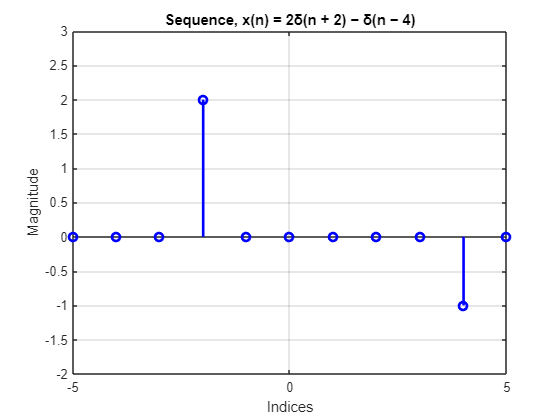

figure;
stem(n,xn,'linewidth',2,'color','b'); grid
title("Sequence, x(n) = 2δ(n + 2) − δ(n − 4)")
xlabel("Indices")
ylabel("Magnitude")
ylim([-2 3])

    e) x(n) = cos(0.04πn) + 0.2w(n), 0 ≤ n ≤ 50, where w(n) is a Gaussian random                                 sequence with zero mean and unit variance.

mu=input('Enter the value of mean = ');
var=input('Enter the value of Variation = ');
sigma=sqrt(var)

sigma = 1

xn=1:50;
pdf = @(x) (1/sqrt(2*sigma^2))*exp((-(x-mu).^2)/(2*sigma^2));
figure
subplot(311)
fplot(pdf,  [0 50]); grid
cos_f = @(x) cos(0.04*pi*x)

cos_f = function_handle with value:
    @(x)cos(0.04*pi*x)


subplot(312)
fplot(cos_f, [0 50]); grid
xn =@(x) cos_f + pdf

xn = function_handle with value:
    @(x)cos_f+pdf


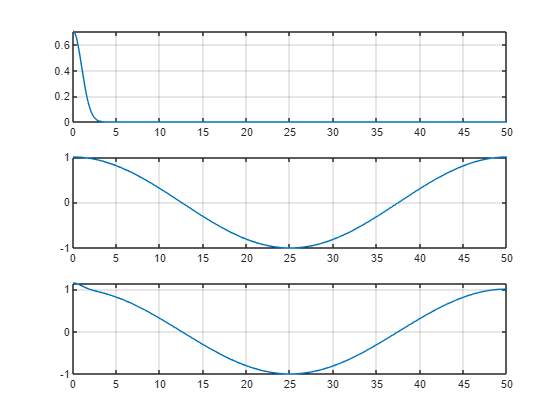

xn1 =@(x) cos(0.04*pi*x) + 0.2*(1/sqrt(2*sigma^2))*exp((-(x-mu).^2)/(2*sigma^2));
subplot(313)
fplot(xn1, [0 50]); grid

2nd Method

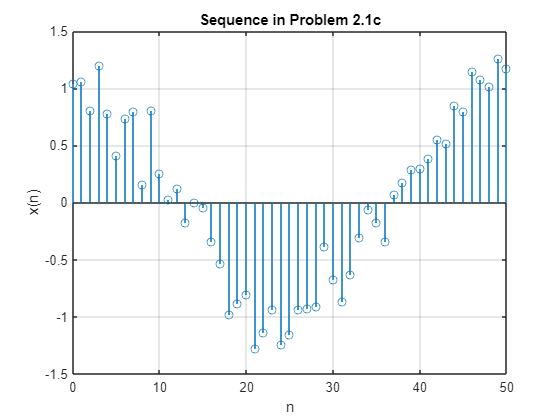

n = 0:50; 
xn = cos(0.04*pi*n)+0.2*randn(size(n));
figure
stem(n,xn); grid
title('Sequence in Problem 2.1c')
xlabel('n'); 
ylabel('x(n)');

2) Let x(n) = {1, 2, 3, 4, 5, 6, 7, 6, 5, 4, 3, 2, 1}. Determine and plot the following sequence

    a) x1(n) = 2x(n − 5) − 3x(n + 4)

n = -2:10 

n =     -2    -1     0     1     2     3     4     5     6     7     8     9    10


xn = [1:7,6:-1:1]

xn =      1     2     3     4     5     6     7     6     5     4     3     2     1


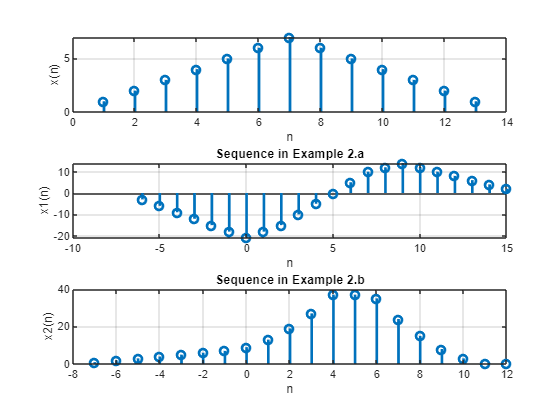

figure
subplot(311)
stem(xn,'linewidth',2); grid
xlabel('n'); 
ylabel(['x(n)']);

[x11,n11] = sigshift(xn,n,5);
[x12,n12] = sigshift(xn,n,-4);
[x1,n1] = sigadd(2*x11,n11,-3*x12,n12);
subplot(312)
stem(n1,x1,'linewidth',2); grid
title('Sequence in Example 2.a')
xlabel('n'); 
ylabel('x1(n)');

[x21,n21] = sigfold(xn,n); 
[x21,n21] = sigshift(x21,n21,3);
[x22,n22] = sigshift(xn,n,2); 
[x22,n22] = sigmult(xn,n,x22,n22);
[x2,n2] = sigadd(x21,n21,x22,n22);
subplot(313)
stem(n2,x2,'linewidth',2); grid
title(['Sequence in Example 2.b'])
xlabel('n'); 
ylabel('x2(n)');

3) For given matrices A and B, perform matrix multiplication and scalar multiplication

A=input('Enter the Elements of First Matrix = ');
B=input('Enter the Elements of Second Matrix = ');

[r1 c1] = size(A);
[r2 c2] = size(B);
if c1 ~= r2
    disp ('* not able to multiply matrices *');
end

for i = 1 : r1;
    for j = 1 : c2;
        s = 0;
        for k = 1 : c1
            A(i,k);
            B(k,j);
            s = s + A(i,k) * B(k,j);
        end
        C(i,j) = s;
    end
end
display(C, 'Output Matrix')

   111   126   141
   174   198   222
   237   270   303




% Compare our result with a multiplication by Matlab
display(A*B, 'Using Direct Method')

   111   126   141
   174   198   222
   237   270   303



4) Generate the complex-valued signal x(n) = e^(−0.1+j0.3)n , −10 ≤ n ≤ 10 

and plot its magnitude, phase, the real part, and the imaginary part in four separate subplots. 

n=-10:10

n =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


x_n=exp((-0.1+0.3i)*n)

x_n =   -2.6911 - 0.3836i  -2.2237 - 1.0512i  -1.6411 - 1.5033i  -1.0166 - 1.7383i  -0.4140 - 1.7745i   0.1166 - 1.6446i   0.5406 - 1.3904i   0.8391 - 1.0574i   1.0081 - 0.6897i   1.0558 - 0.3266i   1.0000 + 0.0000i   0.8644 + 0.2674i   0.6757 + 0.4623i   0.4605 + 0.5803i   0.2429 + 0.6248i   0.0429 + 0.6050i  -0.1247 + 0.5345i  -0.2507 + 0.4287i  -0.3313 + 0.3035i  -0.3676 + 0.1738i  -0.3642 + 0.0519i


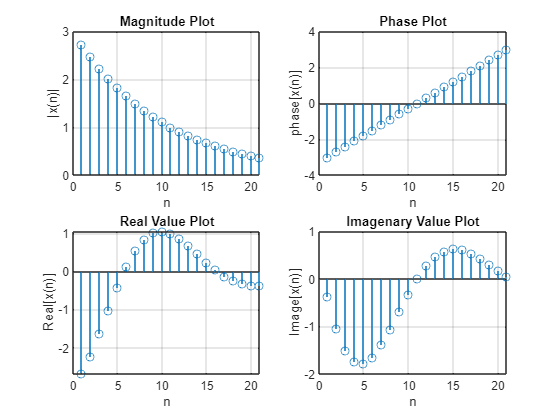

figure
subplot(221)
stem(abs(x_n)); grid
title('Magnitude Plot')
xlabel('n'); 
ylabel('|x(n)|');
subplot(222)
stem(angle(x_n)); grid
title('Phase Plot')
xlabel('n'); 
ylabel('phase[x(n)]');
subplot(223)
stem(real(x_n)); grid
title('Real Value Plot')
xlabel('n'); 
ylabel('Real[x(n)]');
subplot(224)
stem(imag(x_n)); grid
xlabel('n'); 
ylabel('Image[x(n)]');
title('Imagenary Value Plot')

5) Given the following two sequences x(n) = {3, 11, 7, 0, −1, 4, 2} , −3 ≤ n ≤ 3; h(n) = {2, 3, 0, −5, 2, 1} , −1 ≤ n ≤ 4, determine the convolution y(n) = x(n) ∗ h(n) in MATLAB.

xn=input('Enter the sequence x(n)= ');
hn=input('Enter the sequence h(n)= ');
m=length(xn);
n=length(hn);
X=[xn,zeros(1,n)];
H=[hn,zeros(1,m)]; 
for i=1:n+m-1
    yn(i)=0;
    for j=1:m;
        if(i-j+1>0)
            yn(i)=yn(i)+X(j)*H(i-j+1);
        else
        end
    end
end
display(yn, 'Output of Convolution');

     4    13    28    27    18



yn1=conv(xn,hn);
display(yn1, 'Output of Convolution using conv function');

     4    13    28    27    18



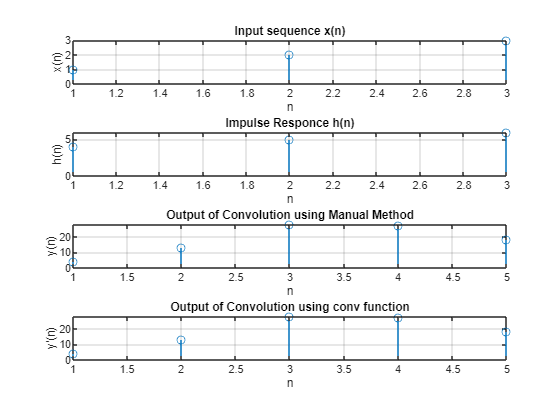


figure
subplot(411)
stem(xn); grid
title('Input sequence x(n)')
xlabel('n')
ylabel('x(n)')

subplot(412)
stem(hn); grid
title('Impulse Responce h(n)')
xlabel('n')
ylabel('h(n)')

subplot(413)
stem(yn); grid
title('Output of Convolution using Manual Method')
xlabel('n')
ylabel('y(n)')

subplot(414)
stem(yn1); grid
title('Output of Convolution using conv function');
xlabel('n')
ylabel("y'(n)")

6) Determine the discrete-time Fourier transform of the following finite-duration sequence at 501 equispaced frequencies between [0,π]: 

a) x1(n) = {1, 1, 1} 

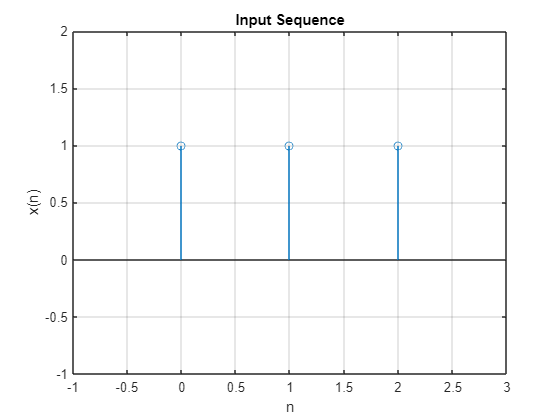

n = 0:2; 
x = [1 1 1];
figure; stem(n,x); grid
xlabel('n'); ylabel('x(n)');
axis([-1 3 -1 2]); title('Input Sequence');

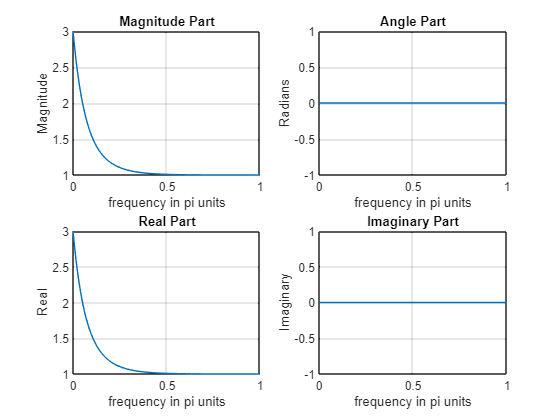


k = 0:500; 
w = (pi/500)*k;  

% DTFT
X = x * (exp(-j*pi/500)) .^ (n'*k); % DTFT Calculation
magX = abs(X); angX = angle(X);
realX = real(X); imagX = imag(X);

figure; subplot(2,2,1); plot(w/pi,magX); grid
xlabel('frequency in pi units'); ylabel('Magnitude');
title('Magnitude Part'); 

subplot(2,2,2); plot(w/pi,angX); grid
xlabel('frequency in pi units'); subplot(2,2,2); 
title('Angle Part'); ylabel('Radians')

subplot(2,2,3); plot(w/pi,realX); grid
xlabel('frequency in pi units');  ylabel('Real');
title('Real Part');

subplot(2,2,4); plot(w/pi,imagX); grid
xlabel('frequency in pi units'); ylabel('Imaginary');
title('Imaginary Part'); 

b) x(n) = {1, 1, 1, 1, 0, 0, 0, 0, 1, 1, 1, 1} 

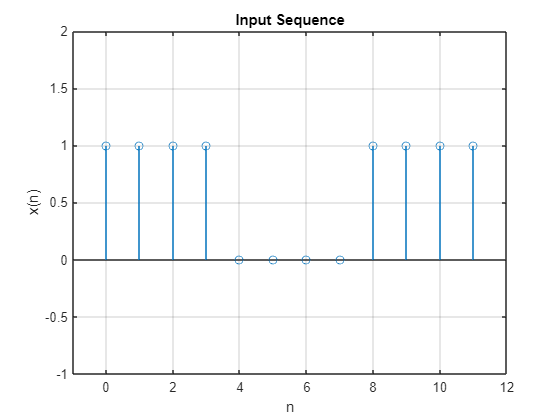

n = 0:11; 
x = [1, 1, 1, 1, 0, 0, 0, 0, 1, 1, 1, 1];

figure; stem(n,x); grid
xlabel('n'); ylabel('x(n)');
axis([-1 12 -1 2]); title('Input Sequence');

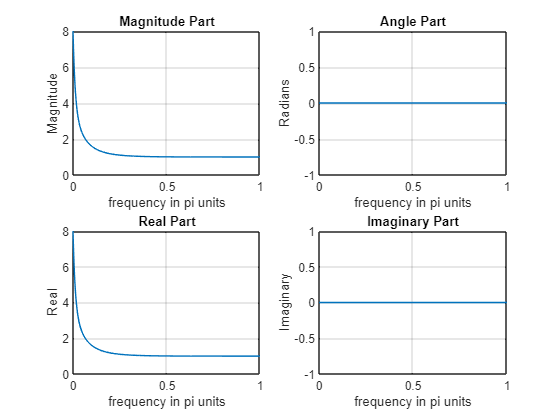


k = 0:500; 
w = (pi/500)*k;  

% DTFT
X = x * (exp(-j*pi/500)) .^ (n'*k); % DTFT Calculation
magX = abs(X); angX = angle(X);
realX = real(X); imagX = imag(X);

figure; subplot(2,2,1); plot(w/pi,magX); grid
xlabel('frequency in pi units'); ylabel('Magnitude');
title('Magnitude Part'); 

subplot(2,2,2); plot(w/pi,angX); grid
xlabel('frequency in pi units'); subplot(2,2,2); 
title('Angle Part'); ylabel('Radians')

subplot(2,2,3); plot(w/pi,realX); grid
xlabel('frequency in pi units');  ylabel('Real');
title('Real Part');

subplot(2,2,4); plot(w/pi,imagX); grid
xlabel('frequency in pi units'); ylabel('Imaginary');
title('Imaginary Part'); 

c) x2(n) = {1, 2, 3, 4, 5} 

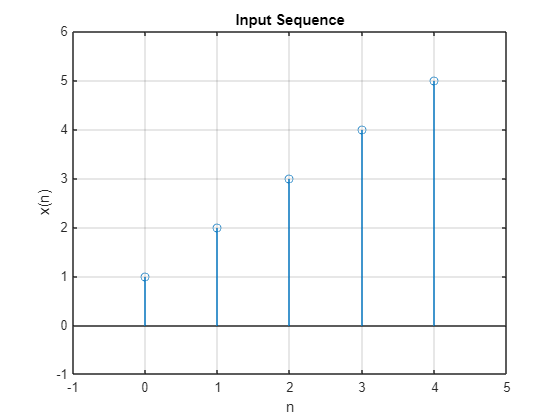

n = 0:4; 
x = [1:5];

figure; stem(n,x); grid
xlabel('n'); ylabel('x(n)');
axis([-1 5 -1 6]); title('Input Sequence');

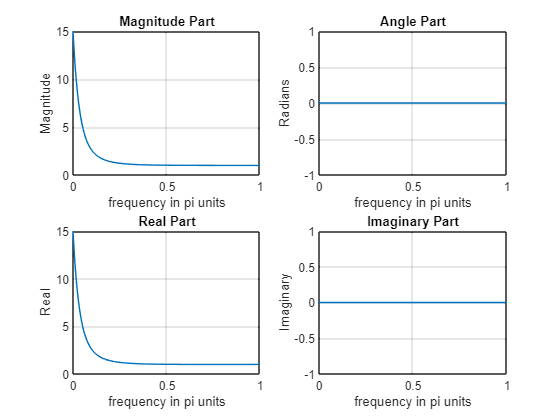


k = 0:500; % DTFT Points
w = (pi/500)*k;  

% DTFT
X = x * (exp(-j*pi/500)) .^ (n'*k); % DTFT Calculation
magX = abs(X); angX = angle(X);
realX = real(X); imagX = imag(X);

figure; subplot(2,2,1); plot(w/pi,magX); grid
xlabel('frequency in pi units'); ylabel('Magnitude');
title('Magnitude Part'); 

subplot(2,2,2); plot(w/pi,angX); grid
xlabel('frequency in pi units'); subplot(2,2,2); 
title('Angle Part'); ylabel('Radians')

subplot(2,2,3); plot(w/pi,realX); grid
xlabel('frequency in pi units');  ylabel('Real');
title('Real Part');

subplot(2,2,4); plot(w/pi,imagX); grid
xlabel('frequency in pi units'); ylabel('Imaginary');
title('Imaginary Part'); 

d) x3(n) = {sin(πn/5)} , n = {1, 2, ....10}

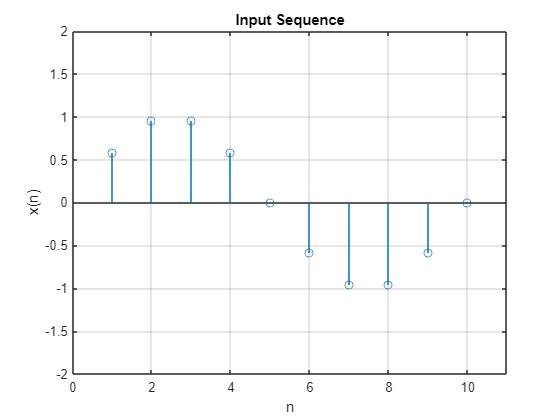

n = 1:10; 
x = sin(pi*n/5);

figure; stem(n,x); grid
xlabel('n'); ylabel('x(n)');
axis([0 11 -2 2]); title('Input Sequence');

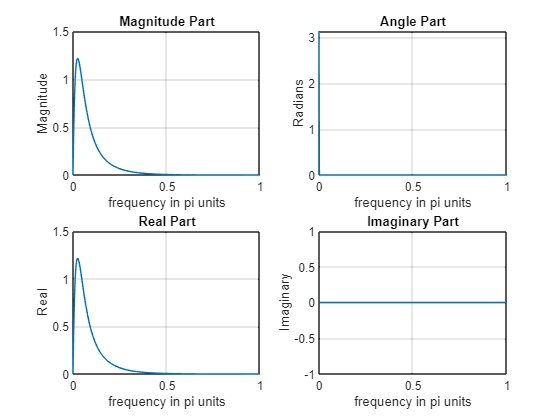


k = 0:500; % DTFT Points
w = (pi/500)*k;  

% DTFT
X = x * (exp(-j*pi/500)) .^ (n'*k); % DTFT Calculation
magX = abs(X); angX = angle(X);
realX = real(X); imagX = imag(X);

figure; subplot(2,2,1); plot(w/pi,magX); grid
xlabel('frequency in pi units'); ylabel('Magnitude');
title('Magnitude Part'); 

subplot(2,2,2); plot(w/pi,angX); grid
xlabel('frequency in pi units'); subplot(2,2,2); 
title('Angle Part'); ylabel('Radians')

subplot(2,2,3); plot(w/pi,realX); grid
xlabel('frequency in pi units');  ylabel('Real');
title('Real Part');

subplot(2,2,4); plot(w/pi,imagX); grid
xlabel('frequency in pi units'); ylabel('Imaginary');
title('Imaginary Part'); 